Lese zunächst die Datei "Haus.jpg" ein und speicher sie in der Variable "haus".

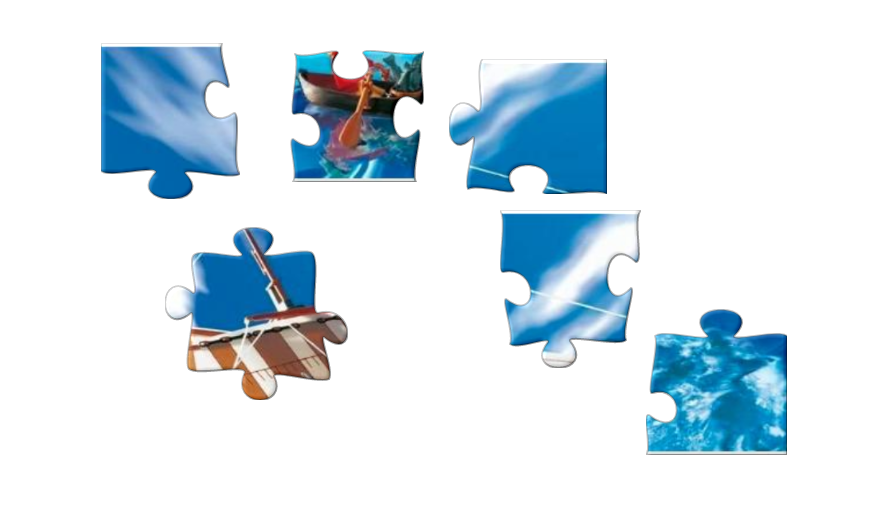

haus = imread('puzzel.png');
imshow(haus);

Um auf dem Bild Merkmale erkennen zu können, musst du es in ein Graustufenbild umwandeln. Speichere das umgewandelte Bild in der Variable "haus_grau".

haus_grau = rgb2gray(haus); 

Bei der Merkmalspunkt Detektion geht es darum möglichst charakteristische Punkte im Bild zu finden. 

Für die Merkmalserkennung gibt es zwei Kategorien von Verfahren. Die sogenannten Blob Detektoren und die Corner Detektoren.

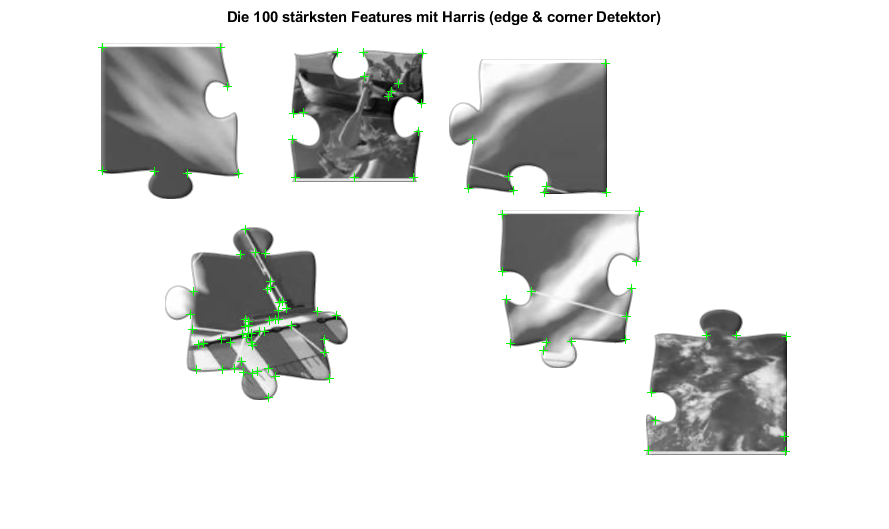

features = detectHarrisFeatures(haus_grau);
imshow(haus_grau);
title('Die 100 stärksten Features mit Harris (edge & corner Detektor)');
hold on;
plot(selectStrongest(features, 100));

Nun schauen wir uns einen Blob Detektor genauer an, das sogenannte SURF Verfahren. Bei der Ausgabe kannst du dir mit der Option "ShowScale", den Kreis proportional zum Maßstab des erkannten Merkmals anzeigen lassen. Der eigentliche Merkmalspunkt ist dabei genau mittig.

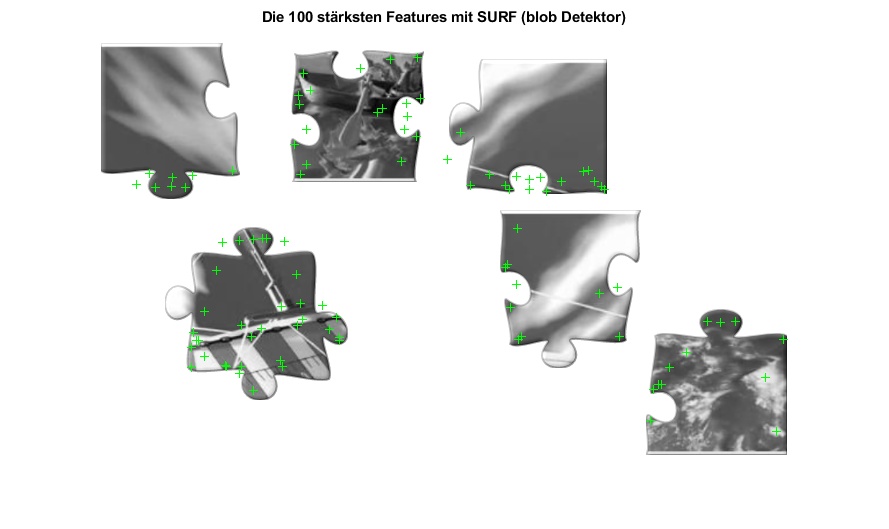

features = detectSURFFeatures(haus_grau);
imshow(haus_grau);
title('Die 100 stärksten Features mit SURF (blob Detektor)');
hold on;

plot(selectStrongest(features, 100), 'ShowScale',false, 'ShowOrientation', false);